## divide train set and test set

data = X;
label = y;

% ratio = 0.75;
% num_train = floor(length(label)*ratio); 
% choose = randperm(length(label));

## cars 

vsels = [];
RMSECVs = [];
minRMSECVs = [];
iternum = 200;
RMSECV_min = 1;

for i = 1:iternum
    Cars = feature_cars(data(choose(1:num_train), :),...
                      label(choose(1:num_train)), 7, 5, 'center', 50);
    vsel_incre = Cars.vsel;
    minRMSECV_incre = Cars.minRMSECV;    
    RMSECV_incre = Cars.RMSECV;  
    
    vsels = [vsels, vsel_incre];
    RMSECVs = [RMSECVs, RMSECV_incre];
    minRMSECVs = [minRMSECVs, minRMSECV_incre];
    
    if minRMSECV_incre < RMSECV_min
        RMSECV_min = minRMSECV_incre;
        vsel_best = vsel_incre;
    end
    
end

The 10th variable sampling finished.
The 20th variable sampling finished.
The 30th variable sampling finished.
The 40th variable sampling finished.
The 50th variable sampling finished.
The 10th subset finished.
The 20th subset finished.
The 30th subset finished.
The 40th subset finished.
The 50th subset finished.
The 10th variable sampling finished.
The 20th variable sampling finished.
The 30th variable sampling finished.
The 40th variable sampling finished.
The 50th variable sampling finished.
The 10th subset finished.
The 20th subset finished.
The 30th subset finished.
The 40th subset finished.
The 50th subset finished.
The 10th variable sampling finished.
The 20th variable sampling finished.
The 30th variable sampling finished.
The 40th variable sampling finished.
The 50th variable sampling finished.
The 10th subset finished.
The 20th subset finished.
The 30th subset finished.
The 40th subset finished.
The 50th subset finished.
The 10th variable sampling finished.
The 20th variable 

vsel_best

vsel_best =     17    18    21    22    23    27    34    41    42    43   121   156   233   234   262   290   319   320   328   377   378


RMSECV_min

RMSECV_min =       0.36314


freqs = [];

for j = 1:length(effshift)
    freq = sum(vsels == j);
    freqs = [freqs, freq];
end

format short g

vsel = find(freqs >= floor(iternum * 0.5))

vsel =     17    18    19    21    22    23    24    25    26    27    40    41    42    43   156   179   180   197   198   232   233   234   261   289   290   318   319   320   328   329


effshift(vsel)

ans =        465.23       469.23       473.22       481.21        485.2       489.19       493.17       497.15       501.14       505.11       556.63       560.57       564.52       568.46       999.87       1084.4         1088       1149.8       1153.4       1275.1       1278.7       1282.2       1377.2       1474.2       1477.6       1573.1       1576.5       1579.9       1606.9       1610.3



CV = plscvfold(data(choose(1:num_train), vsel), label(choose(1:num_train)), 7);  

The 1th group finished.
The 2th group finished.
The 3th group finished.
The 4th group finished.
The 5th group finished.
The 6th group finished.
The 7th group finished.
The 8th group finished.
The 9th group finished.
The 10th group finished.


   
CV.RMSE_min

ans =        0.3813


CV.Rsquare_max     

ans =        0.8855


## vsel_spa

data = X;
train_data  = data(choose(1:num_train), vsel_spa1);
train_label = label(choose(1:num_train));
test_data   = data(choose(num_train+1:end), vsel_spa1);
test_label  = label(choose(num_train+1:end));

*
optimization finished, #iter = 69
nu = 1.000000
obj = -8.471627, rho = 0.034260
nSV = 138, nBSV = 138
*
optimization finished, #iter = 69
nu = 0.992806
obj = -8.435831, rho = 0.935015
nSV = 138, nBSV = 138
*
optimization finished, #iter = 64
nu = 0.962406
obj = -7.908287, rho = -0.957700
nSV = 128, nBSV = 128
*
optimization finished, #iter = 69
nu = 0.992806
obj = -8.507983, rho = 0.938043
nSV = 138, nBSV = 138
*
optimization finished, #iter = 64
nu = 0.962406
obj = -7.910824, rho = -0.961934
nSV = 128, nBSV = 128
*
optimization finished, #iter = 65
nu = 0.955224
obj = -7.987532, rho = -0.989690
nSV = 128, nBSV = 128
Total nSV = 272
*
optimization finished, #iter = 68
nu = 1.000000
obj = -8.340411, rho = 0.034410
nSV = 136, nBSV = 136
*
optimization finished, #iter = 68
nu = 0.992701
obj = -8.312087, rho = 0.935778
nSV = 136, nBSV = 136
*
optimization finished, #iter = 64
nu = 0.969697
obj = -7.906016, rho = -0.953298
nSV = 128, nBSV = 128
*
optimization finished, #iter = 68
nu = 0.9

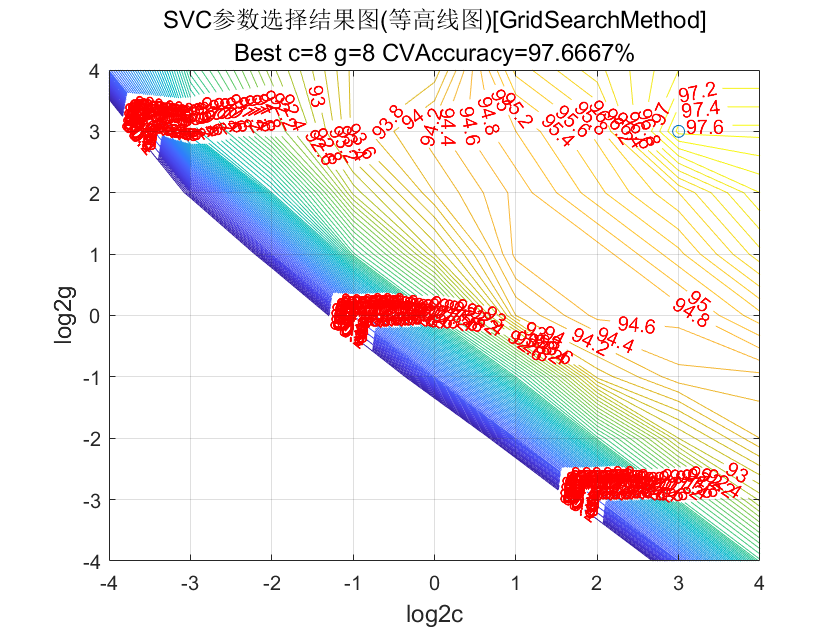

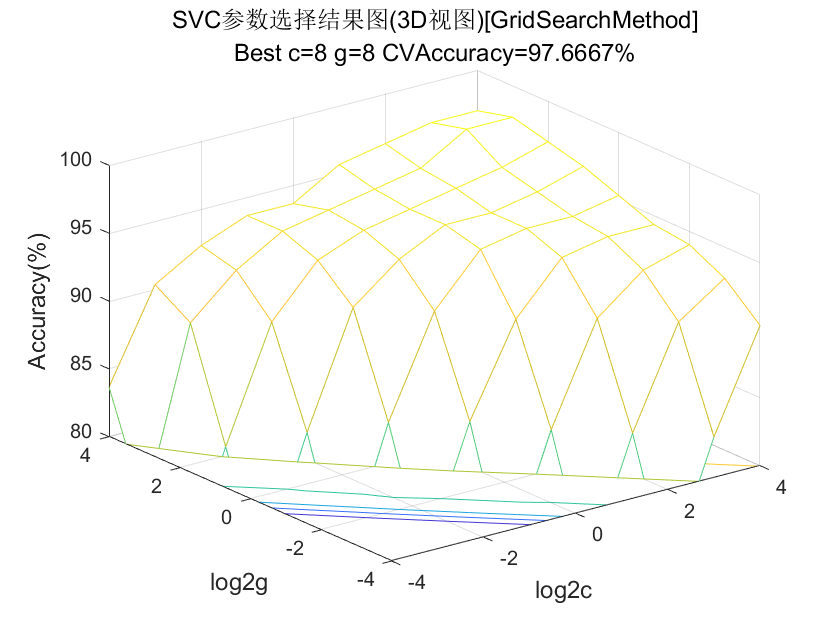

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,-4, 4, -4, 4, 10, 1, 1, 0.2);

toc

历时 4.618192 秒。


*
optimization finished, #iter = 66
nu = 0.889954
obj = -93.098280, rho = -0.177499
nSV = 130, nBSV = 128
*
optimization finished, #iter = 36
nu = 0.485478
obj = -46.207011, rho = 0.082440
nSV = 70, nBSV = 68
*
optimization finished, #iter = 58
nu = 0.790848
obj = -87.643838, rho = 0.151703
nSV = 114, nBSV = 112
*
optimization finished, #iter = 30
nu = 0.410959
obj = -40.355734, rho = 0.089082
nSV = 60, nBSV = 60
*
optimization finished, #iter = 53
nu = 0.698630
obj = -78.196816, rho = 0.082381
nSV = 103, nBSV = 101
*
optimization finished, #iter = 66
nu = 0.902778
obj = -102.000261, rho = -0.153421
nSV = 130, nBSV = 130
Total nSV = 273
*
optimization finished, #iter = 66
nu = 0.888322
obj = -91.671898, rho = -0.150195
nSV = 130, nBSV = 128
*
optimization finished, #iter = 37
nu = 0.497814
obj = -46.280788, rho = 0.065206
nSV = 72, nBSV = 70
*
optimization finished, #iter = 59
nu = 0.807978
obj = -88.016129, rho = 0.102350
nSV = 116, nBSV = 114
*
optimization finished, #iter = 34
nu = 

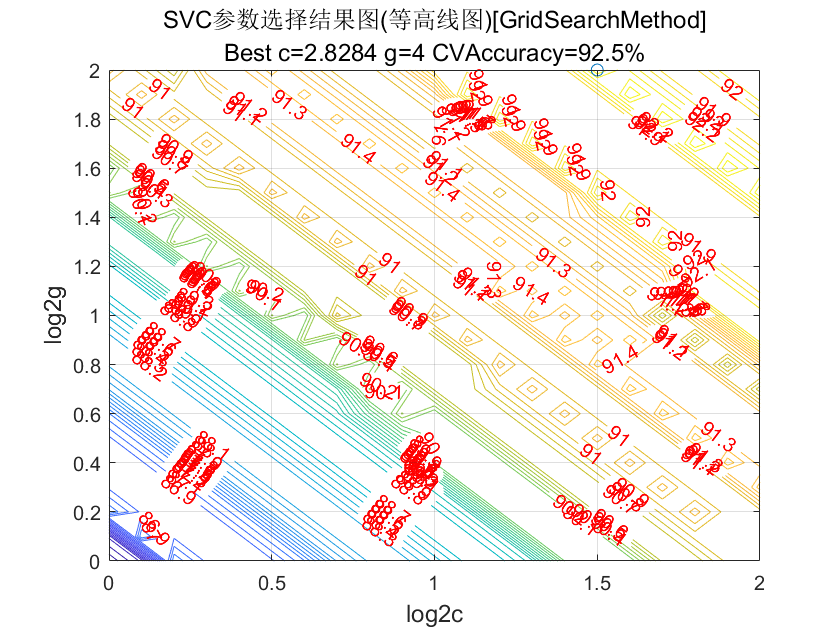

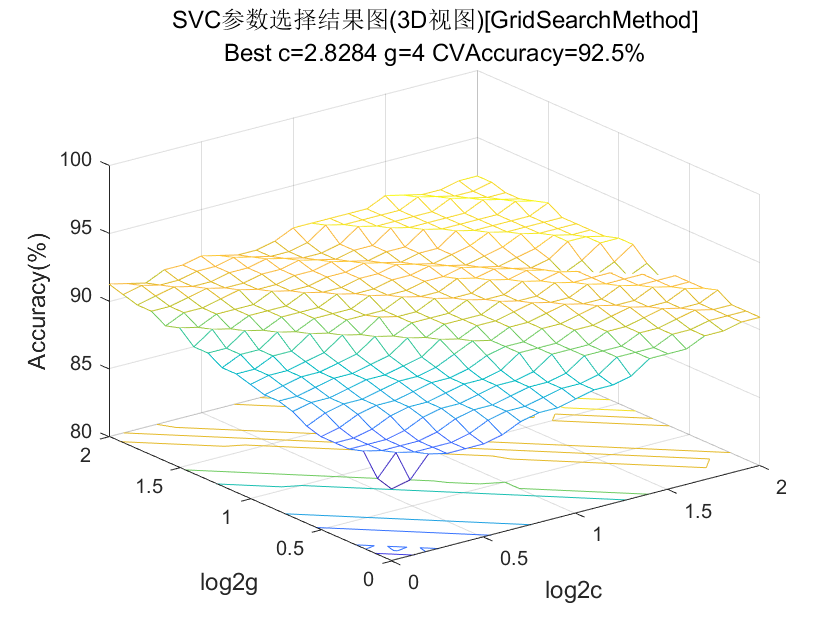

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,0, 2, 0, 2, 10, 0.1, 0.1, 0.1);

toc

历时 18.624280 秒。


s = 0;
t = 0;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

*
optimization finished, #iter = 64
nu = 0.139429
obj = -98.524297, rho = 4.541230
nSV = 24, nBSV = 20
*
optimization finished, #iter = 35
nu = 0.113525
obj = -83.801359, rho = 1.056080
nSV = 18, nBSV = 15
*
optimization finished, #iter = 27
nu = 0.212814
obj = -162.664458, rho = 3.088258
nSV = 33, nBSV = 29
*
optimization finished, #iter = 47
nu = 0.111973
obj = -78.873461, rho = -0.145317
nSV = 20, nBSV = 14
*
optimization finished, #iter = 144
nu = 0.170871
obj = -127.201956, rho = -4.591434
nSV = 28, nBSV = 22
*
optimization finished, #iter = 85
nu = 0.594254
obj = -585.613698, rho = -9.758427
nSV = 90, nBSV = 85
Total nSV = 154



[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);

Accuracy = 94.3333% (283/300) (classification)


[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

Accuracy = 97% (97/100) (classification)


## vsel_best

data = X;
train_data  = data(choose(1:num_train), vsel_best);
train_label = label(choose(1:num_train));
test_data   = data(choose(num_train+1:end), vsel_best);
test_label  = label(choose(num_train+1:end));

*
optimization finished, #iter = 69
nu = 1.000000
obj = -8.593911, rho = 0.005864
nSV = 138, nBSV = 138
*
optimization finished, #iter = 69
nu = 0.992806
obj = -8.407204, rho = 0.924034
nSV = 138, nBSV = 138
*
optimization finished, #iter = 65
nu = 0.962406
obj = -7.934725, rho = -0.958811
nSV = 128, nBSV = 128
*
optimization finished, #iter = 69
nu = 0.992806
obj = -8.465553, rho = 0.941931
nSV = 138, nBSV = 138
*
optimization finished, #iter = 64
nu = 0.962406
obj = -7.964031, rho = -0.971799
nSV = 128, nBSV = 128
*
optimization finished, #iter = 64
nu = 0.955224
obj = -7.973683, rho = -0.986878
nSV = 128, nBSV = 128
Total nSV = 271
*
optimization finished, #iter = 68
nu = 1.000000
obj = -8.466935, rho = 0.005064
nSV = 136, nBSV = 136
*
optimization finished, #iter = 68
nu = 0.992701
obj = -8.285722, rho = 0.923930
nSV = 136, nBSV = 136
*
optimization finished, #iter = 64
nu = 0.969697
obj = -7.930306, rho = -0.955367
nSV = 128, nBSV = 128
*
optimization finished, #iter = 68
nu = 0.9

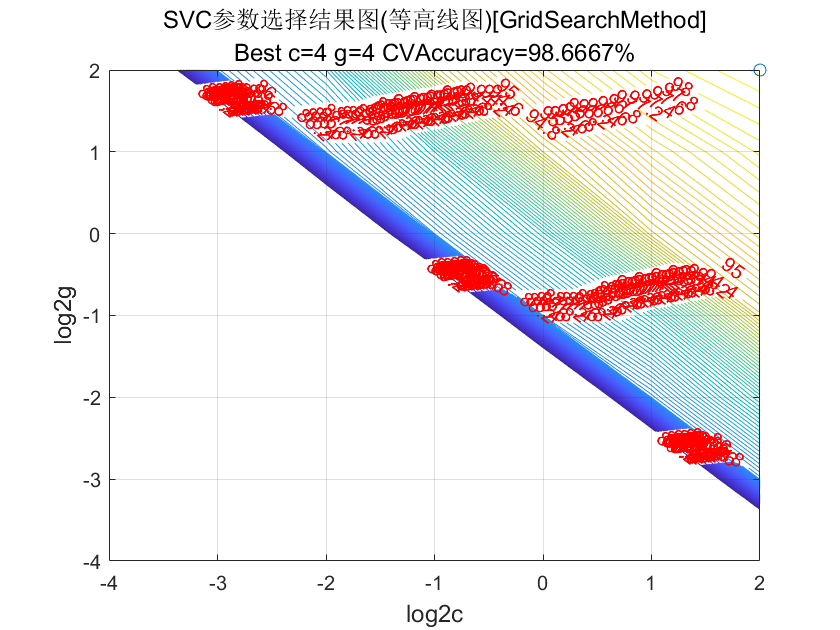

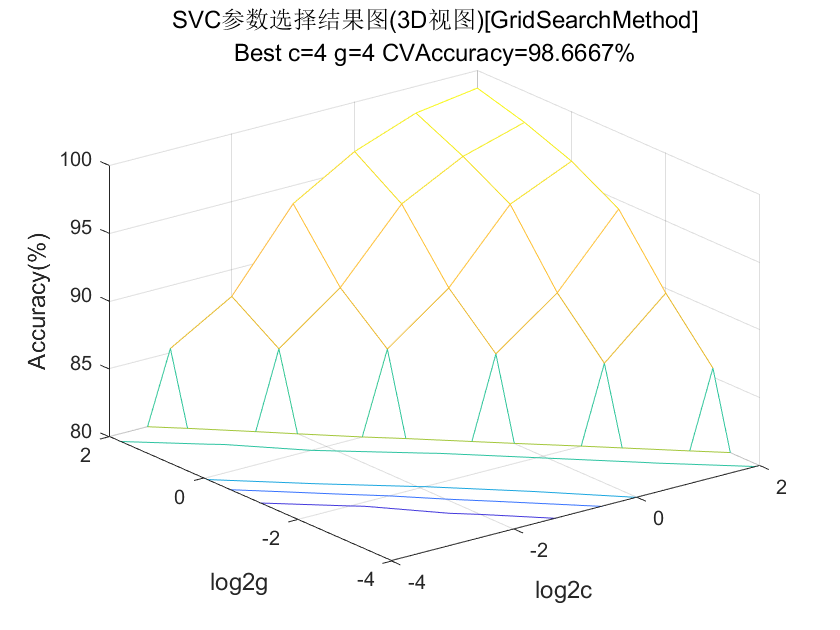

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,-4, 2, -4, 2, 10, 1, 1, 0.2);

toc

历时 3.081472 秒。


*
optimization finished, #iter = 49
nu = 0.496218
obj = -49.137607, rho = -0.110762
nSV = 69, nBSV = 64
*
optimization finished, #iter = 46
nu = 0.606740
obj = -64.201295, rho = -0.006524
nSV = 84, nBSV = 82
*
optimization finished, #iter = 53
nu = 0.710542
obj = -77.319350, rho = 0.117183
nSV = 104, nBSV = 102
*
optimization finished, #iter = 39
nu = 0.540706
obj = -44.985055, rho = 0.109503
nSV = 71, nBSV = 67
*
optimization finished, #iter = 25
nu = 0.305047
obj = -26.979834, rho = 0.203452
nSV = 42, nBSV = 39
*
optimization finished, #iter = 30
nu = 0.339201
obj = -29.973522, rho = 0.125522
nSV = 48, nBSV = 46
Total nSV = 210
*
optimization finished, #iter = 46
nu = 0.495565
obj = -47.270455, rho = -0.122390
nSV = 68, nBSV = 63
*
optimization finished, #iter = 48
nu = 0.629340
obj = -66.538236, rho = -0.010064
nSV = 88, nBSV = 85
*
optimization finished, #iter = 51
nu = 0.718310
obj = -76.797007, rho = 0.232935
nSV = 102, nBSV = 102
*
optimization finished, #iter = 40
nu = 0.547240

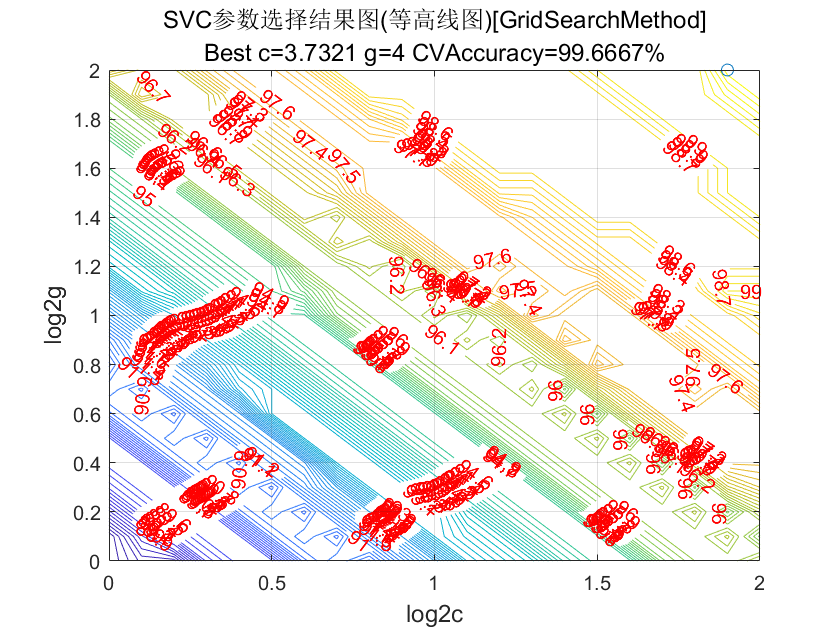

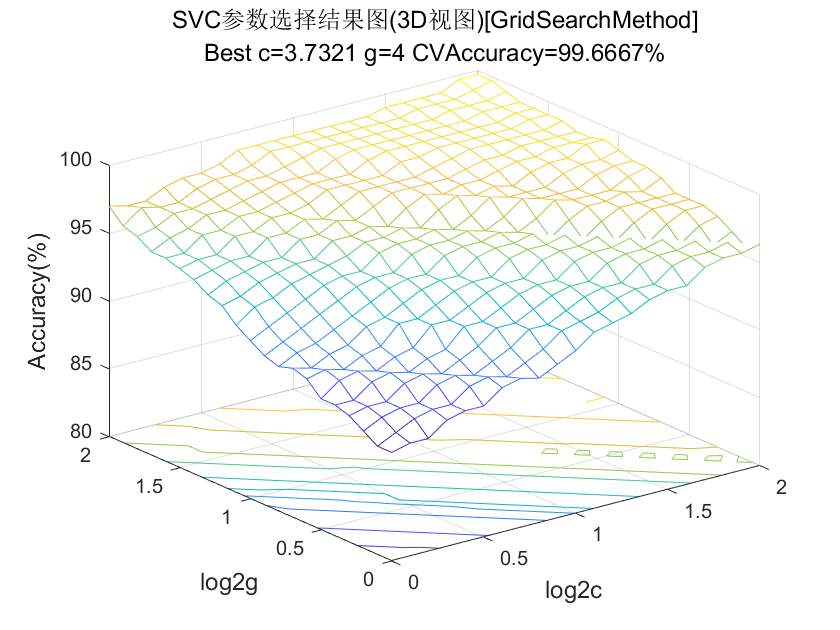

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,0, 2, 0, 2, 10, 0.1, 0.1, 0.1);

toc

历时 21.600986 秒。


% vsel_best
s = 0;
t = 0;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

*
optimization finished, #iter = 57
nu = 0.411552
obj = -144.904169, rho = -1.096785
nSV = 65, nBSV = 60
*
optimization finished, #iter = 23
nu = 0.176631
obj = -67.522789, rho = 3.365101
nSV = 28, nBSV = 25
*
optimization finished, #iter = 36
nu = 0.397821
obj = -169.615085, rho = 4.308045
nSV = 60, nBSV = 58
*
optimization finished, #iter = 19
nu = 0.222222
obj = -81.986141, rho = 5.004965
nSV = 35, nBSV = 33
*
optimization finished, #iter = 43
nu = 0.494937
obj = -209.030292, rho = 6.532136
nSV = 74, nBSV = 71
*
optimization finished, #iter = 51
nu = 0.556212
obj = -249.916785, rho = -7.825551
nSV = 84, nBSV = 81
Total nSV = 196



[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);

Accuracy = 95% (285/300) (classification)


[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

Accuracy = 94% (94/100) (classification)


## vsel

data = X;
train_data  = data(choose(1:num_train), vsel);
train_label = label(choose(1:num_train));
test_data   = data(choose(num_train+1:end), vsel);
test_label  = label(choose(num_train+1:end));

*
optimization finished, #iter = 63
nu = 0.933333
obj = -7.762901, rho = -0.948448
nSV = 126, nBSV = 126
*
optimization finished, #iter = 66
nu = 0.956522
obj = -8.187859, rho = -0.967752
nSV = 132, nBSV = 132
*
optimization finished, #iter = 72
nu = 1.000000
obj = -8.959360, rho = 0.005468
nSV = 144, nBSV = 144
*
optimization finished, #iter = 64
nu = 0.976744
obj = -7.806845, rho = 0.969638
nSV = 126, nBSV = 126
*
optimization finished, #iter = 63
nu = 0.933333
obj = -7.637184, rho = 0.911359
nSV = 126, nBSV = 126
*
optimization finished, #iter = 67
nu = 0.956522
obj = -8.076454, rho = 0.935333
nSV = 132, nBSV = 132
Total nSV = 273
*
optimization finished, #iter = 62
nu = 0.932331
obj = -7.643290, rho = -0.950601
nSV = 124, nBSV = 124
*
optimization finished, #iter = 66
nu = 0.963504
obj = -8.192187, rho = -0.969069
nSV = 132, nBSV = 132
*
optimization finished, #iter = 71
nu = 1.000000
obj = -8.836017, rho = 0.006001
nSV = 142, nBSV = 142
*
optimization finished, #iter = 63
nu = 0.9

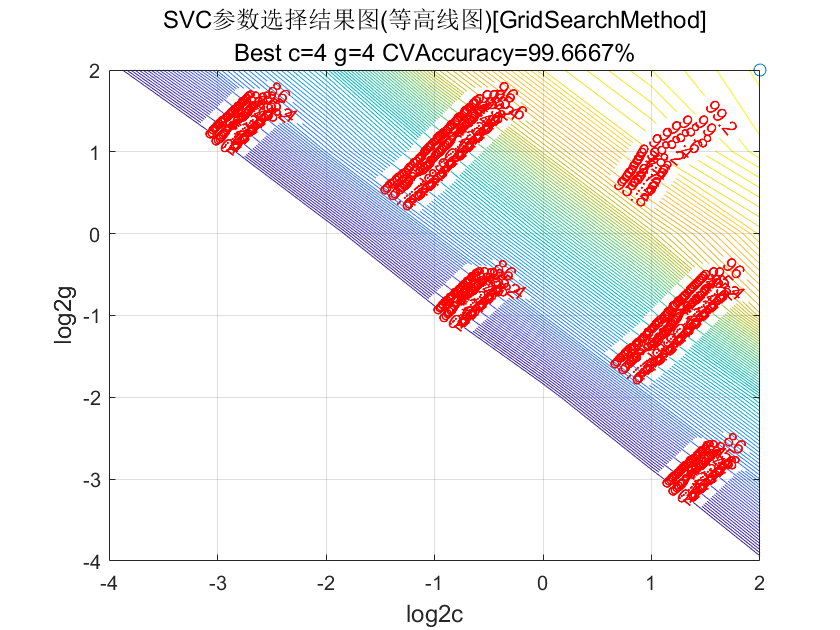

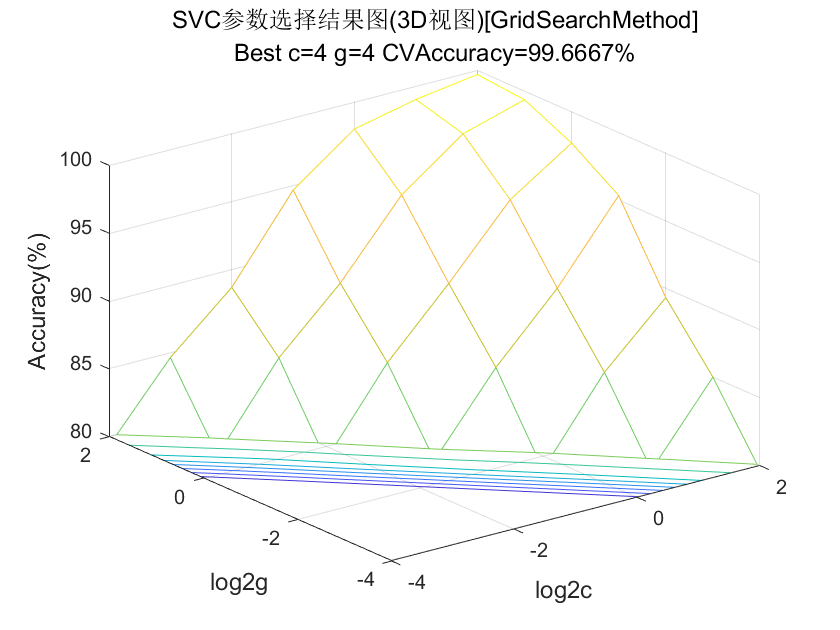

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,-4, 2, -4, 2, 10, 1, 1, 0.2);

toc

历时 3.077307 秒。


*
optimization finished, #iter = 36
nu = 0.410130
obj = -40.010245, rho = -0.178901
nSV = 57, nBSV = 54
*
optimization finished, #iter = 41
nu = 0.553066
obj = -57.042495, rho = -0.079454
nSV = 78, nBSV = 75
*
optimization finished, #iter = 49
nu = 0.643156
obj = -70.158780, rho = 0.064711
nSV = 95, nBSV = 92
*
optimization finished, #iter = 38
nu = 0.435640
obj = -34.888302, rho = -0.011822
nSV = 58, nBSV = 53
*
optimization finished, #iter = 23
nu = 0.237037
obj = -20.672433, rho = 0.232113
nSV = 33, nBSV = 31
*
optimization finished, #iter = 25
nu = 0.285915
obj = -24.907035, rho = 0.130695
nSV = 41, nBSV = 38
Total nSV = 195
*
optimization finished, #iter = 40
nu = 0.399708
obj = -38.061469, rho = -0.169561
nSV = 56, nBSV = 52
*
optimization finished, #iter = 42
nu = 0.574096
obj = -58.983624, rho = -0.062461
nSV = 80, nBSV = 77
*
optimization finished, #iter = 46
nu = 0.647887
obj = -69.565677, rho = 0.240437
nSV = 92, nBSV = 92
*
optimization finished, #iter = 35
nu = 0.435211
ob

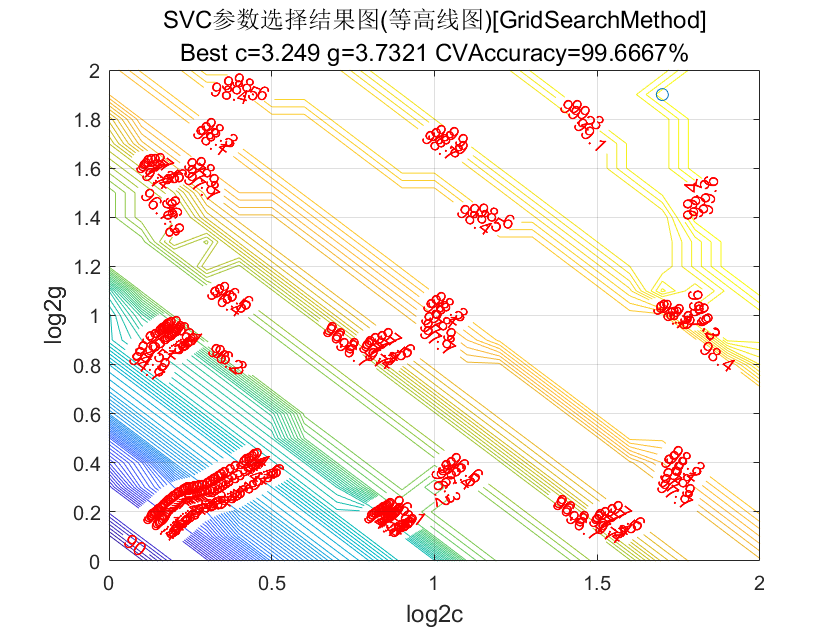

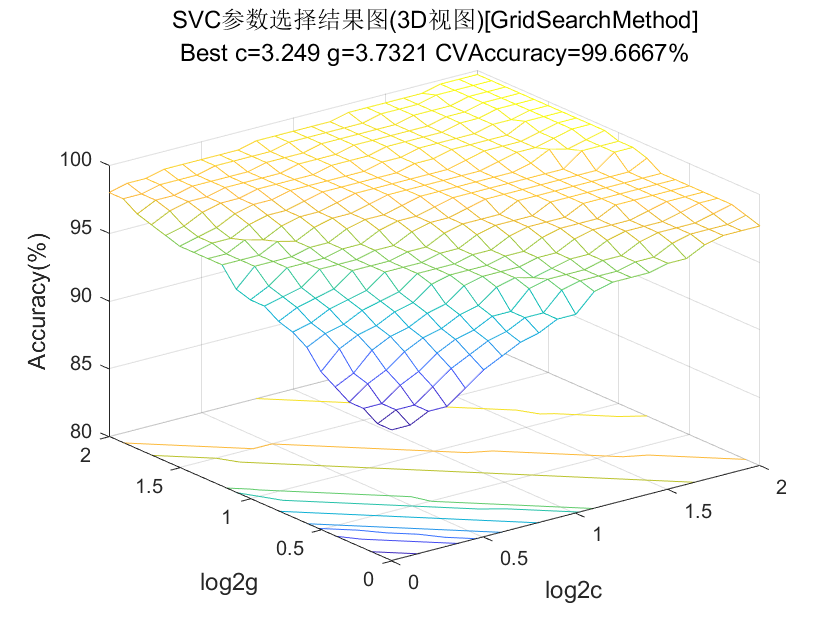

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,0, 2, 0, 2, 10, 0.1, 0.1, 0.1);

toc

历时 21.073366 秒。


% vsel
s = 0;
t = 0;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

*
optimization finished, #iter = 46
nu = 0.321789
obj = -109.769607, rho = -4.729504
nSV = 50, nBSV = 45
*
optimization finished, #iter = 44
nu = 0.483574
obj = -166.725120, rho = -5.369308
nSV = 74, nBSV = 72
*
optimization finished, #iter = 54
nu = 0.547109
obj = -210.404524, rho = 7.455547
nSV = 88, nBSV = 84
*
optimization finished, #iter = 43
nu = 0.303151
obj = -85.041842, rho = 0.039614
nSV = 45, nBSV = 40
*
optimization finished, #iter = 34
nu = 0.177650
obj = -55.211612, rho = 2.817055
nSV = 28, nBSV = 24
*
optimization finished, #iter = 23
nu = 0.217641
obj = -64.639110, rho = 3.945321
nSV = 35, nBSV = 31
Total nSV = 189


[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);

Accuracy = 95.6667% (287/300) (classification)


[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

Accuracy = 94% (94/100) (classification)


## confusion matrix

% plotconfusion(test_label.', test_pred_label.');

# model = libsvmtrain(label, data, ‘option’)

# [predicted_label, accuracy,decision_values] = libsvmpredict(y_test, x_test, model)

% options:
% -s svm_type : set type of SVM (default 0)
% 	0 -- C-SVC		(multi-class classification)
% 	1 -- nu-SVC		(multi-class classification)
% 	2 -- one-class SVM
% 	3 -- epsilon-SVR	(regression)
% 	4 -- nu-SVR		(regression)
% -t kernel_type : set type of kernel function (default 2)
% 	0 -- linear: u'*v
% 	1 -- polynomial: (gamma*u'*v + coef0)^degree
% 	2 -- radial basis function: exp(-gamma*|u-v|^2)
% 	3 -- sigmoid: tanh(gamma*u'*v + coef0)
% 	4 -- precomputed kernel (kernel values in training_set_file)
% -d degree : set degree in kernel function (default 3)
% -g gamma : set gamma in kernel function (default 1/num_features)  
%            gamma越大，支持向量越少，过拟合
% -r coef0 : set coef0 in kernel function (default 0)
% -c cost : set the parameter C of C-SVC, epsilon-SVR, and nu-SVR (default 1)
%           C是惩罚系数（正则化参数的倒数），即对误差的宽容度，c越大，容易过拟合
% -n nu : set the parameter nu of nu-SVC, one-class SVM, and nu-SVR (default 0.5)
% -p epsilon : set the epsilon in loss function of epsilon-SVR (default 0.1)
% -m cachesize : set cache memory size in MB (default 100)
% -e epsilon : set tolerance of termination criterion (default 0.001)
% -h shrinking : whether to use the shrinking heuristics, 0 or 1 (default 1)
% -b probability_estimates : whether to train a SVC or SVR model for probability estimates, 0 or 1 (default 0)
% -wi weight : set the parameter C of class i to weight*C, for C-SVC (default 1)
% -v n: n-fold cross validation mode(default 5)
% -q : quiet mode (no outputs)

% iter为迭代次数，
% nu 与前面的操作参数-n nu 相同，
% obj为SVM文件转换为的二次规划求解得到的最小值，
% rho 为判决函数的常数项b，
% nSV 为支持向量个数，
% nBSV为边界上的支持向量个数，
% Total nSV为支持向量总个数。
% 训练后的模型保存为文件*.model，用记事本打开其内容如下：
% svm_type c_svc % 训练所采用的svm类型，此处为C- SVC
% kernel_type rbf %训练采用的核函数类型，此处为RBF核
% gamma 0.0769231 %设置核函数中的g ，默认值为1/ k
% nr_class 2 %分类时的类别数，此处为两分类问题
% total_sv 132 %总共的支持向量个数
% rho 0.424462 %决策函数中的常数项b
% label 1 -1%类别标签
% nr_sv 64 68 %各类别标签对应的支持向量个数